%% 第一部分：采样周期 T = 0.001s 的情况
T=0.001;                    % 采样周期为1ms
f=1/T;                      % 采样频率
fp=200;                     % 通带截止频率200Hz
fs=350;                     % 阻带截止频率350Hz
wp=fp*2*pi;                 % 将频率转换为角频率（弧度/秒）
ws=fs*2*pi;
rp=3;rs=35;                 % 通带波纹和阻带衰减指标（dB）

% 脉冲响应不变法设计
[N,wn1]=buttord(wp,ws,rp,rs,'s');    % 计算模拟滤波器阶数和截止频率
[B,A]=butter(N,wn1,'s');              % 设计模拟巴特沃兹滤波器
[n1,d1]=impinvar(B,A,f);              % 使用脉冲响应不变法进行数字化
[h1,w11]=freqz(n1,d1,'whole');          % 计算数字滤波器的频率响应

% 双线性变换法设计
wp=2*f*tan(fp/f*pi);                  % 频率预畸变
ws=2*f*tan(fs/f*pi);
[N,wn2]=buttord(wp,ws,rp,rs,'s');     % 计算模拟滤波器阶数和截止频率
[A,B]=butter(N,wn2,'s');              % 设计模拟巴特沃兹滤波器
[n2,d2]=bilinear(A,B,f);              % 使用双线性变换进行数字化

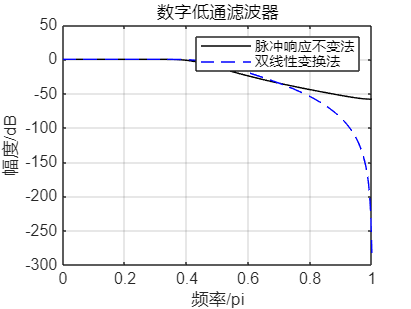

[h2,w12]=freqz(n2,d2,'whole');          % 计算数字滤波器的频率响应

% 绘图
w11=w11/pi;
w12=w12/pi;                               % 将频率归一化到[0,1]
figure(1);
plot(w11,20*log10(abs(h1)),'k',w12,20*log10(abs(h2)),'b--');
grid on;
xlabel('频率/pi');ylabel('幅度/dB');
legend('脉冲响应不变法','双线性变换法');
title('数字低通滤波器');
xlim([0, 1])


%% 第二部分：采样周期 T = 0.0001s 的情况
% 备注同上，懒得写了
T=0.0001;                   % 采样周期为0.1ms
f=1/T;
fp=200;
fs=350;
wp=fp*2*pi;
ws=fs*2*pi;
rp=3;rs=35;
[N,wn1]=buttord(wp,ws,rp,rs,'s');
[B,A]=butter(N,wn1,'s');
[n1,d1]=impinvar(B,A,f);
[h1,w21]=freqz(n1,d1,'whole');
%双线性变换
wp=2*f*tan(fp/f*pi);
ws=2*f*tan(fs/f*pi);
[N,wn2]=buttord(wp,ws,rp,rs,'s');
[A,B]=butter(N,wn2,'s');
[n2,d2]=bilinear(A,B,f);

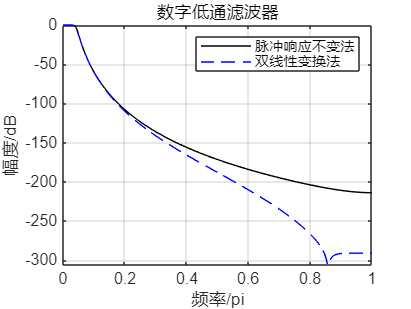

[h2,w22]=freqz(n2,d2,'whole');
w21=w21/pi;
w22=w22/pi;
figure(1);
plot(w21,20*log10(abs(h1)),'k',w22,20*log10(abs(h2)),'b--');
grid on;
xlabel('频率/pi');ylabel('幅度/dB');
legend('脉冲响应不变法','双线性变换法');
title('数字低通滤波器');
xlim([0, 1])